# Loop method for multiple pipelines

## Example problem: 

A portion of a municipal water distribution network is shown below: 

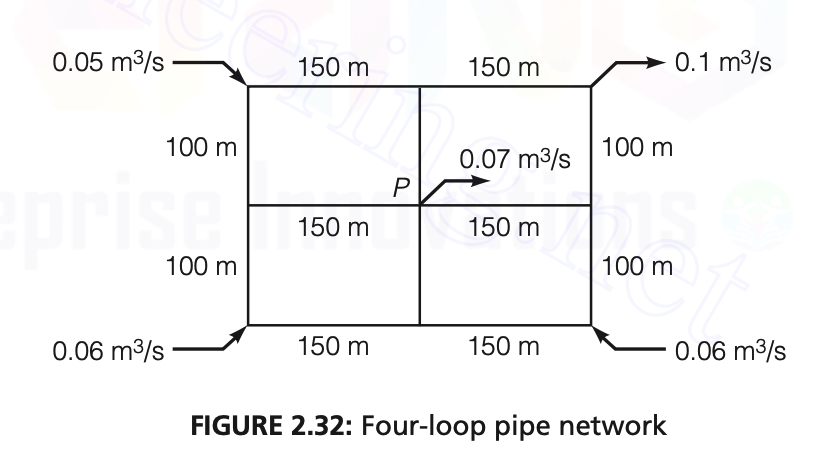

All pipes have diameters of 0.3m, and roughness coefficient k = 0.00026.

**Use the Hardy Cross method to find the flow in each pipe. **

## **Steps to solve: **

1) Make an initial guess for the flow distribution. This guess for flows must satisfy continuity (flow in must equal flow out at each junction). 

2) Calculate the error in the estimated flows ($\Delta Q$) for each loop. Add $\Delta Q$ to the flow estimate to get a new flow estimate. 

3) Iterate until $\Delta Q$ is acceptably small (we converge on the actual flow rate). 

## Sketch out the problem and make initial guess for flow distribution

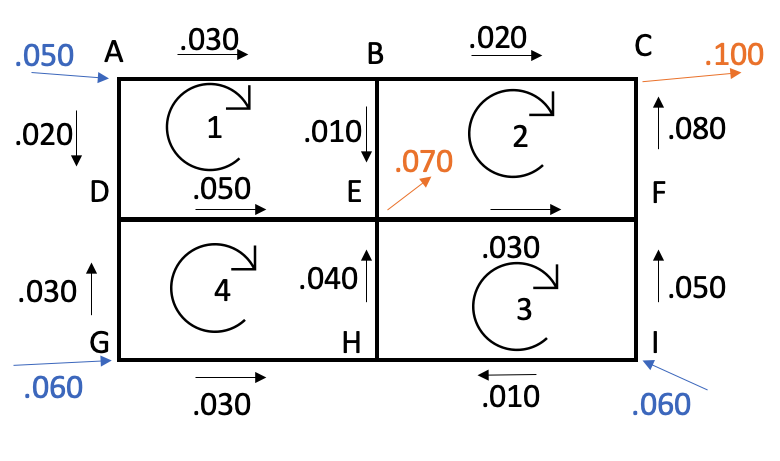

Here, we're going to store all of the pipe information in a table for convenience. In general, it would probably be easiest to create this table in a speadsheet and then import it into MATLAB, but in this example I'm creating the table directly to keep things self-contained. 

The following code constructs a table with one row for each pipe, and columns for Q and L. 

loop = [1;1;1;1;2;2;2;2;3;3;3;3;4;4;4;4];
pipe = ["AB"; "BE"; "ED"; "DA"; "BC"; "CF"; "FE"; "EB"; "EF"; "FI"; "IH"; "HE"; "DE"; "EH"; "HG"; "GD"];
Q = [0.030; 0.010; -0.050; -0.020; 0.020; -0.080; -0.030; -0.010; 0.030; -0.050; 0.010; 0.040; 0.050; -0.040; -0.030; 0.030];
L = [150; 100; 150; 100; 150; 100; 150; 100; 150; 100; 150; 100; 150; 100; 150; 100];
pipes = table(loop, Q, L, 'RowNames', pipe)

pipes = 16×3 table
          loop      Q       L 
          ____    _____    ___

    AB     1       0.03    150
    BE     1       0.01    100
    ED     1      -0.05    150
    DA     1      -0.02    100
    BC     2       0.02    150
    CF     2      -0.08    100
    FE     2      -0.03    150
    EB     2      -0.01    100
    EF     3       0.03    150
    FI     3      -0.05    100
    IH     3       0.01    150
    HE     3       0.04    100
    DE     4       0.05    150
    EH     4      -0.04    100
    HG     4      -0.03    150
    GD     4       0.03    100


## Head loss 

Using Darcy-Weisbach: 


$$h_L =rQ^n \;$$


Assuming all head losses are due to friction and the Darcy-Weisbach equation is used to calculate head losses: 

$r=\frac{f\;L}{2g{\;D\;A}^2 }$ and $n=2\ldotp$

In MATLAB, we would write this as:

## Friction factor

Friction factor for rough pipe, turbulent flow: 


$$\frac{1}{\sqrt{f}}=-2\;\log \left(\frac{k/D}{3\ldotp 7}\right)$$


In MATLAB:

Let's convert these to functions so they'll be more usable. In MATLAB, local function definitions have to be at the end of the file, so you'll find them at the very end. 

Let's go ahead and define the other variables that were given in the problem. We were given k and D, and we're going to use n=2 for this problem.  

n = 2;
k = 0.00026;
D = 0.3;

Now, we can calculate the friction factor and r for each pipe:

f = calc_f_turbulent(k, D)

f = 0.0190

Calculate r for each pipe: 

pipes.r = calc_r(D, pipes.L, f)

pipes = 16×4 table
          loop      Q       L       r  
          ____    _____    ___    _____

    AB     1       0.03    150    96.75
    BE     1       0.01    100     64.5
    ED     1      -0.05    150    96.75
    DA     1      -0.02    100     64.5
    BC     2       0.02    150    96.75
    CF     2      -0.08    100     64.5
    FE     2      -0.03    150    96.75
    EB     2      -0.01    100     64.5
    EF     3       0.03    150    96.75
    FI     3      -0.05    100     64.5
    IH     3       0.01    150    96.75
    HE     3       0.04    100     64.5
    DE     4       0.05    150    96.75
    EH

## Calculate the error in the estimated flows 

Recall the Hardy Cross equation for the estimate error: 


$${\Delta Q}_i =-\frac{\sum_{j=1}^{\textrm{NP}\left(i\right)} r_{\textrm{ij}} Q_j {\left|Q_j \right|}^{n-1} }{\sum_{j=1}^{\textrm{NP}\left(i\right)} {\textrm{nr}}_{\textrm{ij}} {\left|Q_j \right|}^{n-1} }$$


Again, we'll translate this into functions, which are found at the end of the file.

Next, we'll calculate the error for our initial estimate. 

% Calculate error for initial estimate
 [delta_Q, pipes] = calc_loop(pipes, n)

Loop : 1
delta_Q: 0.00900
Loop : 2
delta_Q: 0.02158
Loop : 3
delta_Q: 0.00274
Loop : 4
delta_Q: -0.00068


delta_Q =     0.0090
    0.0216
    0.0027
   -0.0007


pipes = 16×4 table
          loop        Q          L       r  
          ____    __________    ___    _____

    AB     1           0.039    150    96.75
    BE     1      -0.0025833    100     64.5
    ED     1       -0.040316    150    96.75
    DA     1          -0.011    100     64.5
    BC     2        0.041583    150    96.75
    CF     2       -0.058417    100     64.5
    FE     2       -0.011153    150    96.75
    EB     2       0.0025833    100     64.5
    EF     3        0.011153    150    96.75
    FI     3       -0.047264    100     64.5
    IH     3        0.012736    150    96.75
    HE     3         0.04342    100     64.5
    

Then, we need to iterate until the error is acceptable.

tolerance = 0.000001; 
iteration = 1;
while mean(delta_Q) > tolerance
    fprintf("Iteration: %0.0d", iteration)
 [delta_Q, pipes] = calc_loop(pipes, n);
 iteration = iteration + 1;
end

Iteration: 1

Loop : 1
delta_Q: 0.00107
Loop : 2
delta_Q: 0.00361
Loop : 3
delta_Q: 0.00008
Loop : 4
delta_Q: 0.00038


Iteration: 2

Loop : 1
delta_Q: 0.00026
Loop : 2
delta_Q: 0.00002
Loop : 3
delta_Q: 0.00014
Loop : 4
delta_Q: 0.00012


Iteration: 3

Loop : 1
delta_Q: 0.00005
Loop : 2
delta_Q: 0.00001
Loop : 3
delta_Q: 0.00004
Loop : 4
delta_Q: 0.00003


Iteration: 4

Loop : 1
delta_Q: 0.00001
Loop : 2
delta_Q: 0.00000
Loop : 3
delta_Q: 0.00001
Loop : 4
delta_Q: 0.00001


Iteration: 5

Loop : 1
delta_Q: 0.00000
Loop : 2
delta_Q: 0.00000
Loop : 3
delta_Q: 0.00000
Loop : 4
delta_Q: 0.00000


Iteration: 6

Loop : 1
delta_Q: 0.00000
Loop : 2
delta_Q: 0.00000
Loop : 3
delta_Q: 0.00000
Loop : 4
delta_Q: 0.00000


pipes

pipes = 16×4 table
          loop        Q          L       r  
          ____    __________    ___    _____

    AB     1        0.040409    150    96.75
    BE     1      -0.0048168    100     64.5
    ED     1       -0.039448    150    96.75
    DA     1      -0.0095912    100     64.5
    BC     2        0.045226    150    96.75
    CF     2       -0.054774    100     64.5
    FE     2      -0.0077886    150    96.75
    EB     2       0.0048168    100     64.5
    EF     3       0.0077886    150    96.75
    FI     3       -0.046986    100     64.5
    IH     3        0.013014    150    96.75
    HE     3        0.043158    100     64.5
    

function f = calc_f_turbulent(k, D)
    f= 1./((-2*log10(k./D./3.7)).^2);
end

function r = calc_r(D, L, f)
%r=fL/(2gDA^2)
    g=9.81;
    A=0.25*pi*D.^2;
    r=f.*L./(2.*g.*D.*A.^2);
end

function [num] = calc_delta_Q_num(r, Q, n)
    num = r.*Q.*abs(Q).^(n-1);
end

function [denom] = calc_delta_Q_denom(r, Q, n)
    denom = n.*r.*abs(Q).^(n-1);
end


function [delta_Q, pipes] = calc_loop(pipes, n)
    n_loops = length(unique(pipes.loop));
    delta_Q = ones(n_loops,1);

    shared_pipes = intersect(pipes.Row, reverse(pipes.Row));

    for i=1:n_loops
        loop_pipes = pipes(pipes.loop==i, :);
        loop_pipes.num = calc_delta_Q_num(loop_pipes.r, loop_pipes.Q, n);
        loop_pipes.denom = calc_delta_Q_denom(loop_pipes.r, loop_pipes.Q, n);
        delta_Q(i) = -1* sum(loop_pipes.num) / sum(loop_pipes.denom);

        fprintf("Loop : %0.0f\n", i)
        fprintf("delta_Q: %0.5f\n", delta_Q(i))

        % Update the flow estimates
        pipes{pipes.loop==i, "Q"} = loop_pipes.Q + delta_Q(i);

        loop_shared_pipes = intersect(loop_pipes.Row, shared_pipes);
        for j=1:length(loop_shared_pipes)
            shared_pipe = loop_shared_pipes{j};
            shared_pair = reverse(loop_shared_pipes{j});
            pipes{shared_pair, "Q"} = -pipes{shared_pipe, "Q"};
        end
    end
end